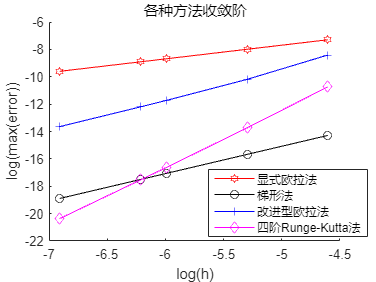

% 收敛阶
clc
clear
clf ('reset')
N=[100 200 400 500 1000];
error1=zeros(1,5);
error2=zeros(1,5);
error3=zeros(1,5);
error4=zeros(1,5);
for l=1:5
    Hfun=@(t,u)(-99*u+exp(t)*(100*cos(t)-sin(t)));
    k = [0 2];
    h = 1/N(l);
    n=fix(2/h)+1;
    u0 = 1;
    [T1,U1] = ODE_ExplicitEuler( Hfun,k,h,u0 );
    [T2,U2]=ODE_TIXING(k,h,u0);
    [T3,U3]=ODE_ImprovedEuler( Hfun,k,h,u0 );
    [T4,U4]=RungeKutta4(k,u0,h);
    E1=zeros(1,n);
    E2=zeros(1,n);
    E3=zeros(1,n);
    E4=zeros(1,n);
    for i=1:n
        E1(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
        E2(i)=abs(U2(i)-exp(T1(i))*cos(T1(i)));
        E3(i)=abs(U3(fix(i/2+1))-exp(T1(fix(i/2+1)))*cos(T1(fix(i/2+1))));
        E4(i)=abs(U4(i)-exp(T1(i))*cos(T1(i)));
    end
    error1(l)=E1(n);
    error2(l)=E2(n);
    error3(l)=E3(n);
    error4(l)=E4(n);
end
hold on
plot(-log(N),log(error1),"r-h")
plot(-log(N),log(error2),"k-o")
plot(-log(N),log(error3),"b-+")
plot(-log(N),log(error4),"m-d")
hold off
legend("显式欧拉法","梯形法","改进型欧拉法","四阶Runge-Kutta法")
xlabel('log(h)');
ylabel('log(max(error))');
title('各种方法收敛阶')
legend("Position", [0.55673,0.16171,0.41881,0.23639])

hhh=zeros(1,5);
for i=1:5
    hhh(i)=1/N(i);
end
hhh=hhh.';
error1=error1.';
error2=error2.';
error3=error3.';
error4=error4.';
TAB=table(hhh,error1,error2,error3,error4);

% 误差
clc
clear
clf ('reset')
k = [0 2];
h = 0.01;
n=fix(2/h)+1;
u0 = 1;
[T1,U1] = RungeKutta4(k,u0,h );
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
    U2(i)=exp(T1(i))*cos(T1(i));
    U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
U2=U2.';
U3=U3.';
hold on
plot(T1,U3,"b-");
k = [0 2];
h = 0.02;
n=fix(2/h)+1;
u0 = 1;
[T1,U1] = RungeKutta4(k,u0,h );
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
    U2(i)=exp(T1(i))*cos(T1(i));
    U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
U2=U2.';
U3=U3.';
plot(T1,U3,'r')
hold off
legend("步长0.01","步长0,02")
title("误差")
legend("Position", [0.14778,0.71522,0.1,0.1])
legend("Position", [0.16325,0.70272,0.27348,0.15441])

% 绝对误差绘图
clc
clear
clf ('reset')
M=[0.97,1.03,1.51,1.96]

M =     0.9700    1.0300    1.5100    1.9600


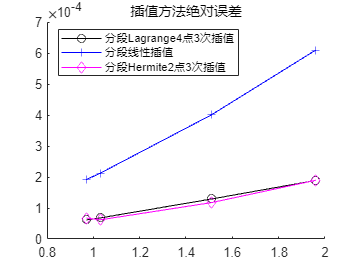

hold on
t=[0 2];
u0 = 1;
h = 0.016;
n=fix(2/h)+1;
[T1,U1] = RungeKutta4(t ,u0, h);
T1=T1.';
U1=U1.';
u1=Lagrange(T1(61:64),U1(61:64),0.97);
u2=Lagrange(T1(64:67),U1(64:67),1.03);
u3=Lagrange(T1(94:97),U1(94:97),1.51);
u4=Lagrange(T1(121:124),U1(121:124),1.96);
delta1=abs(u1-exp(0.97)*cos(0.97));
delta2=abs(u2-exp(1.03)*cos(1.03));
delta3=abs(u3-exp(1.51)*cos(1.51));
delta4=abs(u4-exp(1.96)*cos(1.96));
delta=[delta1,delta2,delta3,delta4];
plot(M,delta,"k-o")
t=[0 2];
u0 = 1;
h = 0.016;
n=fix(2/h)+1;
[T1,U1] = RungeKutta4(t ,u0, h);
T1=T1.';
U1=U1.';
u1=interp1(T1,U1,0.97);
u2=interp1(T1,U1,1.03);
u3=interp1(T1,U1,1.51);
u4=interp1(T1,U1,1.96);
delta1=abs(u1-exp(0.97)*cos(0.97));
delta2=abs(u2-exp(1.03)*cos(1.03));
delta3=abs(u3-exp(1.51)*cos(1.51));
delta4=abs(u4-exp(1.96)*cos(1.96));
delta=[delta1,delta2,delta3,delta4];
plot(M,delta,"b-+")
t=[0 2];
u0 = 1;
h = 0.016;
n=fix(2/h)+1;
[T1,U1] = RungeKutta4(t ,u0, h);
T1=T1.';
U1=U1.';
V1=zeros(n,1);
for i=1:n
    V1(i)=fun(T1(i),U1(i));
end
u1=Hermite(T1(61:62),U1(61:62),V1(61:62),0.97);
u2=Hermite(T1(65:66),U1(65:66),V1(65:66),1.03);
u3=Hermite(T1(95:96),U1(95:96),V1(95:96),1.51);
u4=Hermite(T1(123:124),U1(123:124),V1(123:124),1.96);
delta1=abs(u1-exp(0.97)*cos(0.97));
delta2=abs(u2-exp(1.03)*cos(1.03));
delta3=abs(u3-exp(1.51)*cos(1.51));
delta4=abs(u4-exp(1.96)*cos(1.96));
delta=[delta1,delta2,delta3,delta4];
plot(M,delta,"m-d")
legend("分段Lagrange4点3次插值","分段线性插值","分段Hermite2点3次插值")
title("插值方法绝对误差")
hold off